# Training Unit 6: Automatic Code Generation

Fink Lucas / Teichtmeister Marcus, 05.11.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Generating a Fibonacci Number Generator

Here you can define, which Fibonacci Number should be calculated:

n = 8;

If n exceeds the value 38 (7.18s) the computation time required will be above 10s (12.68s for 39) on the device used.

tic
nthFiboNum = fibonacciCalculation(n)

nthFiboNum =     21.0000e+000

toc

Elapsed time is 0.013700 seconds.


### Input Parameter Handling

Try to feed the fibonacciCalculation function with invalid input parameters, to see if they are handled correctly.

% Test cases
test_cases = {-1; 'a'; [1, 2]; [2, 1]; 5i; 3.41; "Hello Fibonacci."};

% iteration over all test cases
for k = 1:size(test_cases, 1)
    n_input = test_cases{k, 1};

    try
        fibonacciCalculation(n_input);
    catch ME
        fprintf('Test successful #%d %s\n', k, ME.message);
    end
end

Test successful #1 Invalid argument at position 1. Value must be nonnegative.
Test successful #2 Invalid argument at position 1. Value must be numeric.
Test successful #3 Invalid argument at position 1. Value must be a scalar.
Test successful #4 Invalid argument at position 1. Value must be a scalar.
Test successful #5 Invalid argument at position 1. Value must be real.
Test successful #6 Invalid argument at position 1. Value must be integer.
Test successful #7 Invalid argument at position 1. Value must be numeric.


clear

## Generating a Matlab executable function from the Fibonacci function

The MATLAB Coder successfully generated the MEX function, `fibonacciCalculation_mex`, for the entry-point function `fibonacciCalculation(n)`.

**Examination of the Code Generation Report:**

**Source Logic Files:**

- `fibonacciCalculation.c and fibonacciCalculation.h`

**The Executable:**

- `fibonacciCalculation_mex.mexw64`: This is the final compiled **binary MEX file**. It combines the source logic and the interface code

**Interface and Source Files:**

- Also a lot of interface and source files for MEX-code have been created, handling the conversion of data between MATLAB's native format and simple C data types.

n = 12;

The MEX-function (6.55s for n=43 and 10.89s for n=44) is considerably faster than the MATLAB-function (7.18s for n=38). So the maximum number could be increased from 38 to 43.

tic
nthFiboNum = fibonacciCalculation_mex_TU6(n)

nthFiboNum =    144.0000e+000

toc

Elapsed time is 0.010905 seconds.


### Input Parameter Handling for the MEX-Function

Again the fibonacciCalculation function gets invalid input parameters, to see if they are handled correctly.

% Testfälle
test_cases = {-1; 'a'; [1, 2]; [2, 1]; 5i; 3.41; "Hello Fibonacci."};

% Iteration durch die Testfälle
for k = 1:size(test_cases, 1)
    n_input = test_cases{k, 1};

    try
        fibonacciCalculation_mex(n_input);
    catch ME
        fprintf('Test successful #%d %s\n', k, ME.message);
    end
end

Test successful #1 Undefined function 'fibonacciCalculation_mex' for input arguments of type 'double'.
Test successful #2 Undefined function 'fibonacciCalculation_mex' for input arguments of type 'char'.
Test successful #3 Undefined function 'fibonacciCalculation_mex' for input arguments of type 'double'.
Test successful #4 Undefined function 'fibonacciCalculation_mex' for input arguments of type 'double'.
Test successful #5 Undefined function 'fibonacciCalculation_mex' for input arguments of type 'double'.
Test successful #6 Undefined function 'fibonacciCalculation_mex' for input arguments of type 'double'.
Test successful #7 Undefined function 'fibonacciCalculation_mex' for input arguments of type 'string'.


When entering false input parameters to the MEX-Function, it bascially behaves the same as the MATLAB-Function. Just the String of the Error Messages differs, but they carry the same meaning.

clear

## Function Performance Testing

Now the performance of the MEX-Function and the MATLAB-Function is compared

n = 8; 
num_runs = 10000; 

Arrays that store the single function run times:

matlab_times = zeros(1, num_runs);
mex_times = zeros(1, num_runs);

Function Testing:

%% 1. Performance-Test: MATLAB-Funktion (fibonacciCalculation.m)
for i = 1:num_runs
    tic;
    fibonacciCalculation(n); 
    matlab_times(i) = toc;
end

%% 2. Performance-Test: MEX-Funktion (fibonacciCalculation_mex.mexw64)
for i = 1:num_runs
    tic; 
    fibonacciCalculation_mex_TU6(n); 
    mex_times(i) = toc;
end

Calculation of the mean function calculation time over all runs and the time saving in percent when using MEX-Functions instead of MATLAB-Function

% --- Statistical Evaluation ---
mean_matlab_time = mean(matlab_times);
mean_mex_time = mean(mex_times);

std_matlab = std(matlab_times);
std_mex = std(mex_times);

% Calculate time saving in percent
time_saving_percent = ((mean_matlab_time - mean_mex_time) / mean_matlab_time) * 100;
disp(['Mean MATLAB time: ', num2str(mean_matlab_time * 1e6), ' us']);

Mean MATLAB time: 40.3917 us


disp(['Mean MEX time:    ', num2str(mean_mex_time * 1e6), ' us']);

Mean MEX time:    4.4397 us


disp(['Time Saving (using MEX): ', num2str(time_saving_percent), '%']);

Time Saving (using MEX): 89.0084%


### Performance-Visualisation

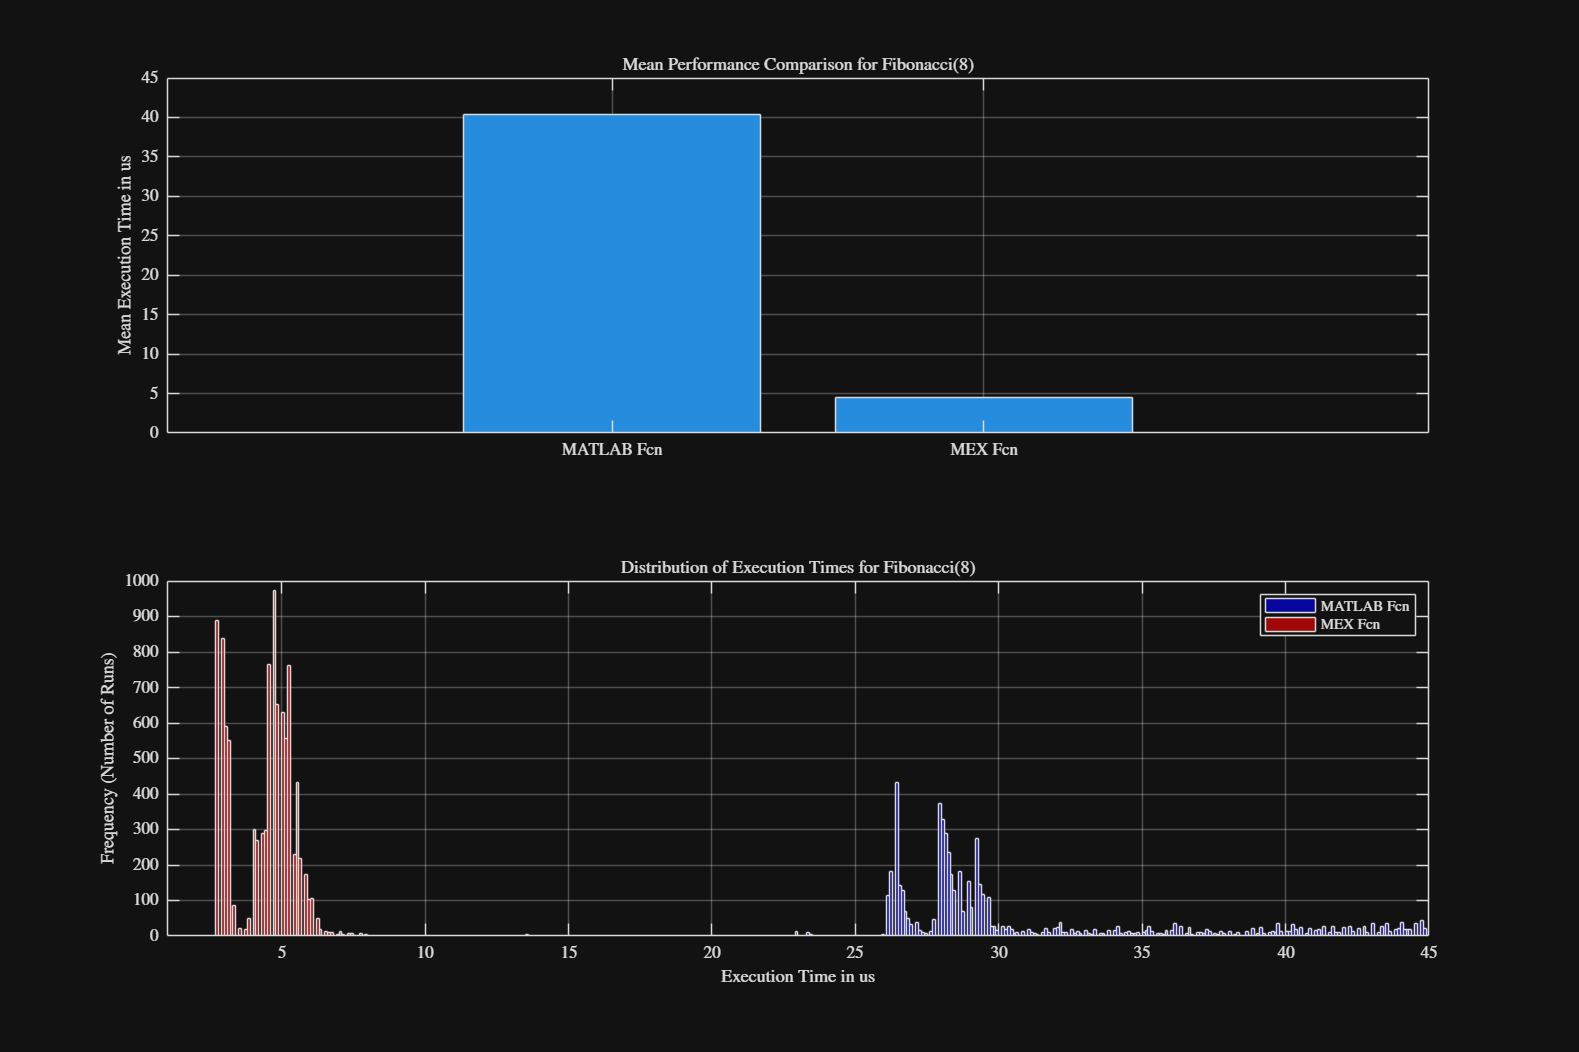

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2,1);

% --- Visualization (Bar Chart) --- 
nexttile
bar_data = [mean_matlab_time, mean_mex_time] * 1e6; 
bar(bar_data);
set(gca, 'XTickLabel', {'MATLAB Fcn', 'MEX Fcn'});
ylabel('Mean Execution Time in us'); 
title(['Mean Performance Comparison for Fibonacci(', num2str(n), ')']);
grid on;
% --- Visualization (Histogram) ---
nexttile
h1 = histogram(matlab_times * 1e6, 'FaceColor', 'b', 'BinWidth', 0.1); 
hold on;
h2 = histogram(mex_times * 1e6, 'FaceColor', 'r', 'BinWidth', 0.1);
legend('MATLAB Fcn', 'MEX Fcn');
xlabel('Execution Time in us');
ylabel('Frequency (Number of Runs)');
title(['Distribution of Execution Times for Fibonacci(', num2str(n), ')']);
xlim([1, 45])
hold off;
grid on;

- In the plot above, a huge difference between Execution Time of MATLAB and MEX-functions can be observed. The MEX-function executes around ~90% faster than the MATLAB-function. Additioonally the MATLAB-functions execution time is much more inconsistent and spreads over a larger time frame.

## Pre-Allocation Testing

Now, the performance benefit of pre-allocating arrays in MATLAB will be demonstrated. First the the fibonacciCalculation will be run without pre-allocation of the storing array an then compared to the pre-allocated version.

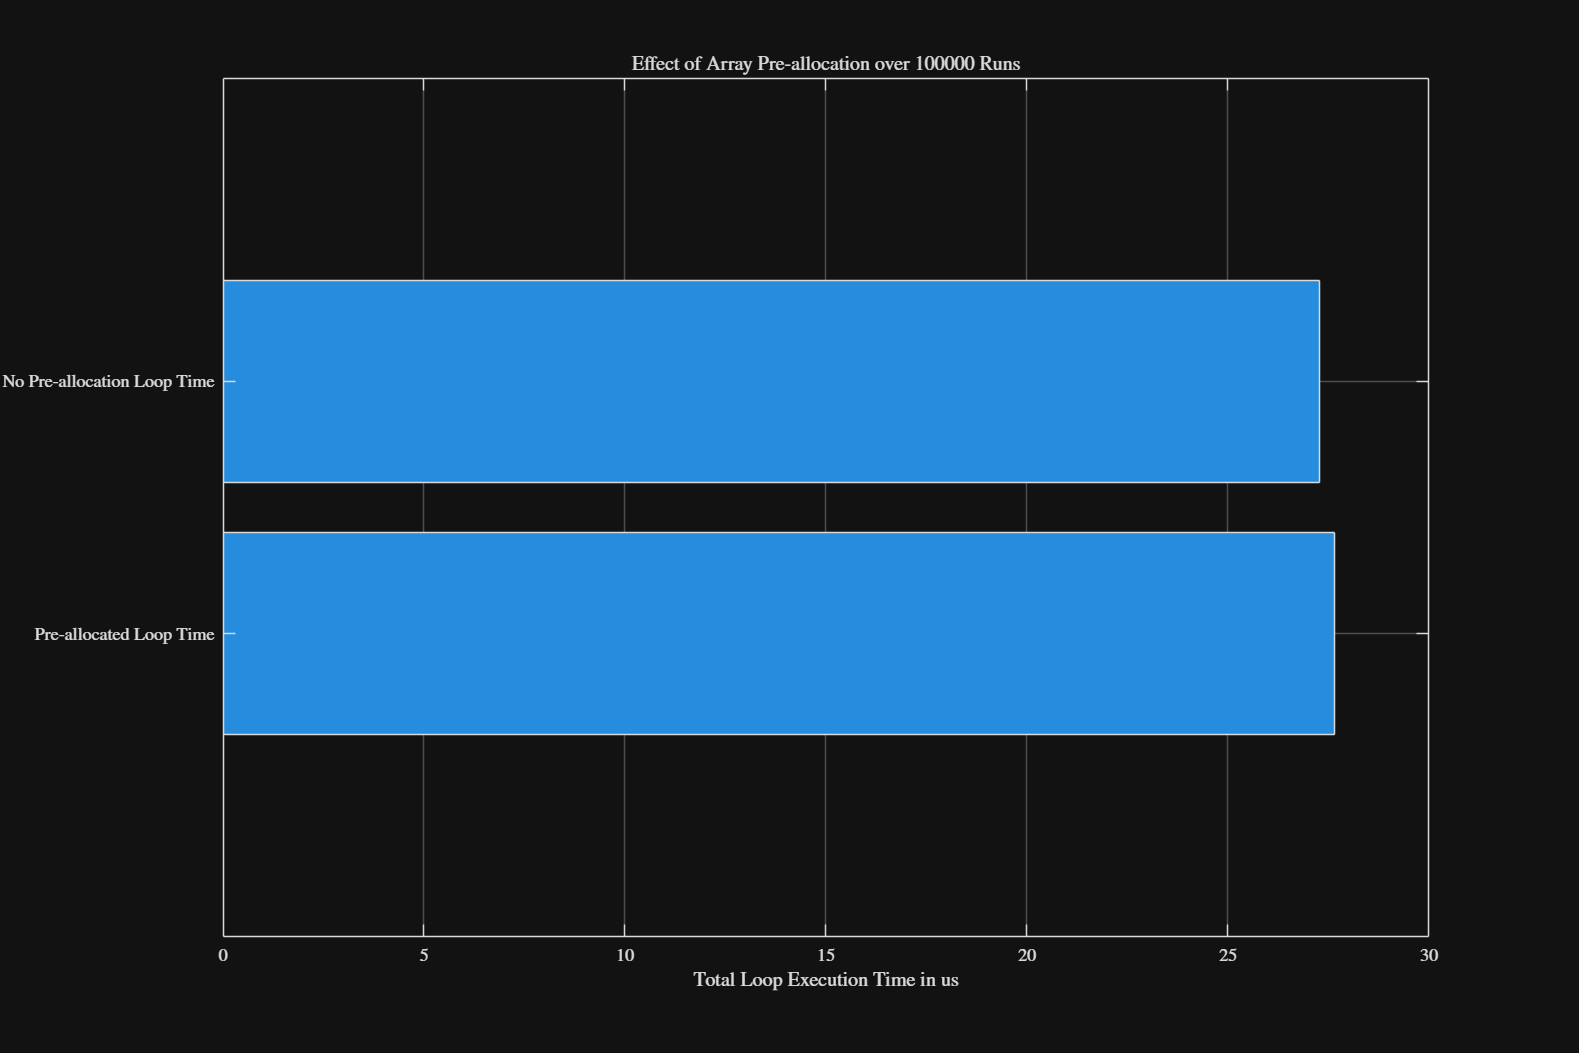

matlab_times_no_prealloc = [];
num_runs_prealloc_test = 100000; 

for i = 1:num_runs_prealloc_test
    tic;
    F_matlab = fibonacciCalculation(n);
    matlab_times_no_prealloc(i) = toc; 
end
mean_matlab_time_no_prealloc = mean(matlab_times_no_prealloc);

matlab_times_prealloc = zeros(1, num_runs_prealloc_test);
for i = 1:num_runs_prealloc_test
    tic;
    F_matlab = fibonacciCalculation(n);
    matlab_times_prealloc(i) = toc;
end
mean_matlab_time_prealloc = mean(matlab_times_prealloc);

% --- Plotting the Effect of Pre-allocation ---
figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
barh([mean_matlab_time_prealloc* 1e6, mean_matlab_time_no_prealloc* 1e6]);
set(gca, 'YTickLabel', {'Pre-allocated Loop Time', 'No Pre-allocation Loop Time'});
xlabel('Total Loop Execution Time in us');
title(['Effect of Array Pre-allocation over ', num2str(num_runs_prealloc_test), ' Runs']);
grid on;

- The bar chart demonstrates the benefit of array pre-allocation in MATLAB, as the Pre-allocated loop time is lower than the No Pre-allocation loop time over 100,000 runs. This performance improvement occurs because pre-allocation avoids the overhead of repeatedly resizing the array during the loop execution. 

disp(['Mean MATLAB time (Pre-allocated): ', num2str(mean_matlab_time_prealloc * 1e6), ' us']);

Mean MATLAB time (Pre-allocated): 27.6606 us


disp(['Mean MATLAB time (No Pre-allocation): ', num2str(mean_matlab_time_no_prealloc * 1e6), ' us']);

Mean MATLAB time (No Pre-allocation): 27.2662 us


clear

## Increasing Calculation Load

Now the performance for the MEX and MATLAB-function is tested and compared over an increasing fibonacci number (n)

n_test = [20, 22, 24, 26]; 
num_runs = 250; 

mean_matlab_times = zeros(1, length(n_test));
mean_mex_times= zeros(1, length(n_test));

for k = 1:length(n_test)
    n_current = n_test(k);
    
    time_matlab_current = zeros(1, num_runs);
    time_mex_current = zeros(1, num_runs);
    
    % 1. MATLAB Function Timing
    for i = 1:num_runs
        tic;
        fibonacciCalculation(n_current); 
        time_matlab_current(i) = toc;
    end
    mean_matlab_times(k) = mean(time_matlab_current);
    
    % 2. MEX Function Timing
    for i = 1:num_runs
        tic;
        fibonacciCalculation_mex_TU6(n_current); 
        time_mex_current(i) = toc;
    end
    mean_mex_times(k) = mean(time_mex_current);
    
end

Evaluating the higher loads performance results

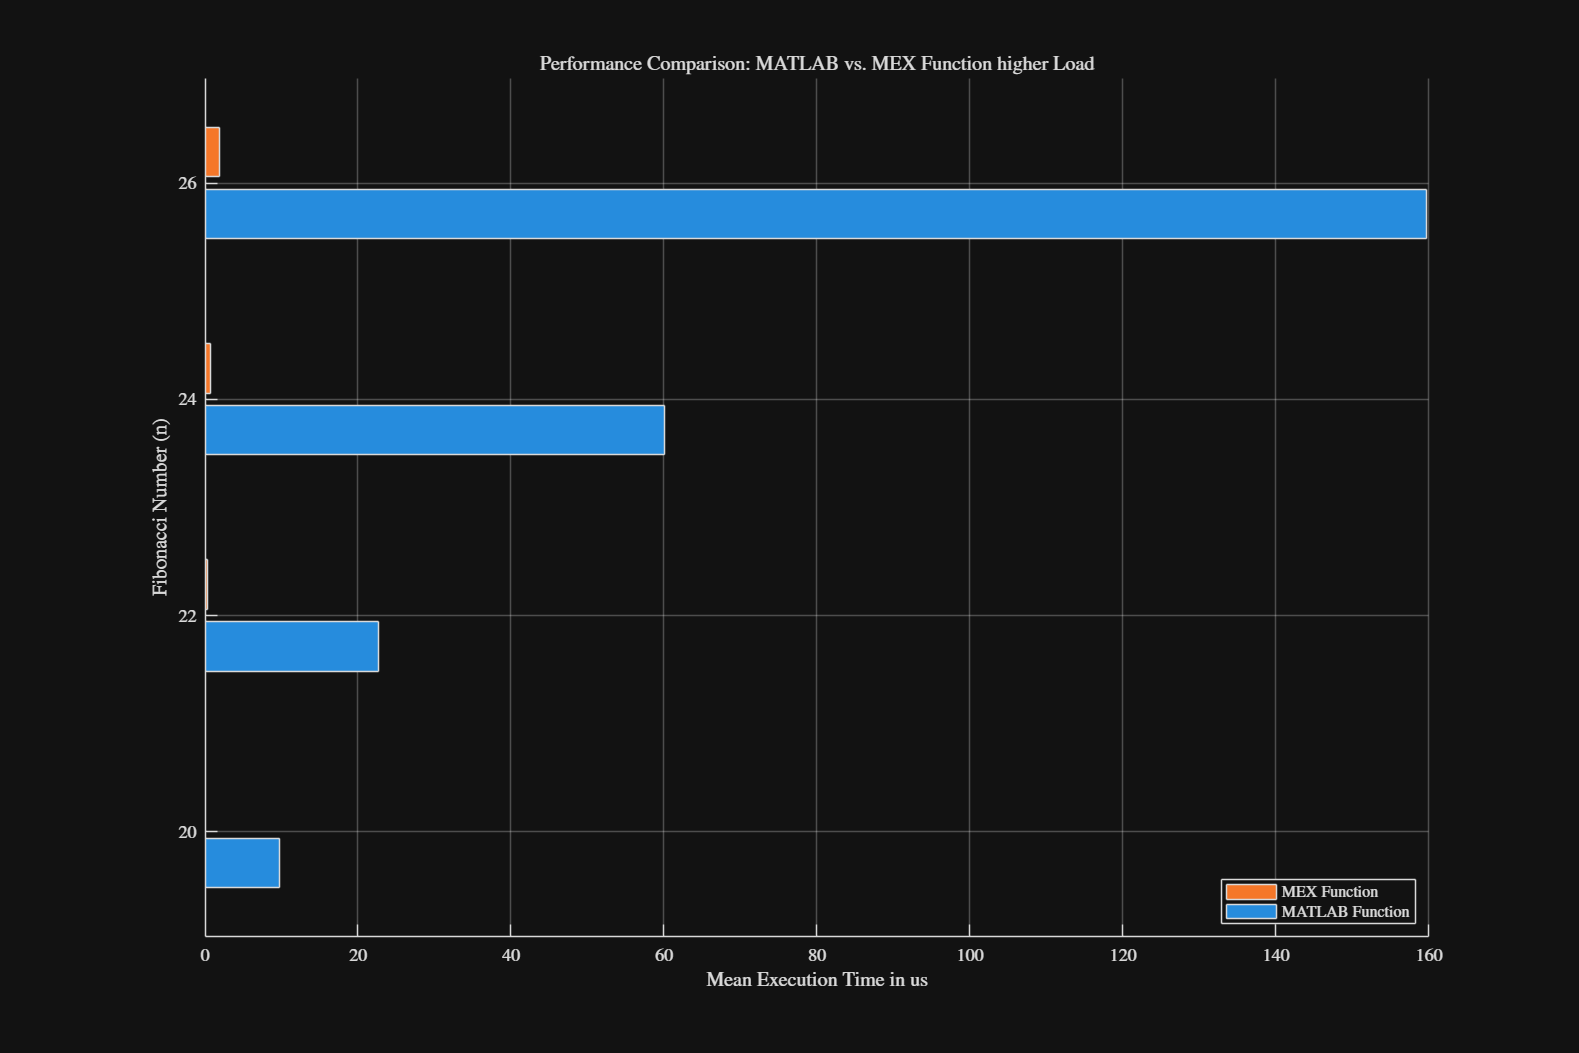

DataMatrix = [mean_matlab_times' * 1000, ...
              mean_mex_times' * 1000]; 

figure('Units', 'normalized', 'Position', [0.1 0.1 0.7 0.7]);
h_bar = barh(DataMatrix); 
yticks(1:length(n_test));
yticklabels(cellstr(num2str(n_test'))); 
xlabel('Mean Execution Time in us');
ylabel('Fibonacci Number (n)');
title('Performance Comparison: MATLAB vs. MEX Function higher Load');
legend({'MATLAB Function', 'MEX Function'}, 'Location', 'SouthEast');
grid on;
box off;

- The bar chart visually confirms that the MEX function significantly outperforms the standard MATLAB function across increasing computational loads, demonstrating the higher efficiency of compiled C/C++ code over interpreted MATLAB code.

clear

## Creating .exe from Fibonacci MATLAB Function

Generating a standalone Windows executable (`.exe`) from the MATLAB function fibonacciCalculation.m

MATLAB Coder cannot directly create a runnable executable because a standard MATLAB function lacks the required C entry point (main function). This entry point is essential for the operating system to start the program, read command-line arguments, and manage I/O.

Solved by modifiying the example main.c file. This custom file now contains the necessary C code to:

- Read the desired Fibonacci number n from the user via the terminal.

- Call the C code generated by MATLAB Coder (fibonacciCalculation).

- Write the result back to the terminal.

The first screenshot displays the MATLAB Coder Report Viewer, confirming the successful generation of C source files and headers from the fibonacciCalculation.m function.

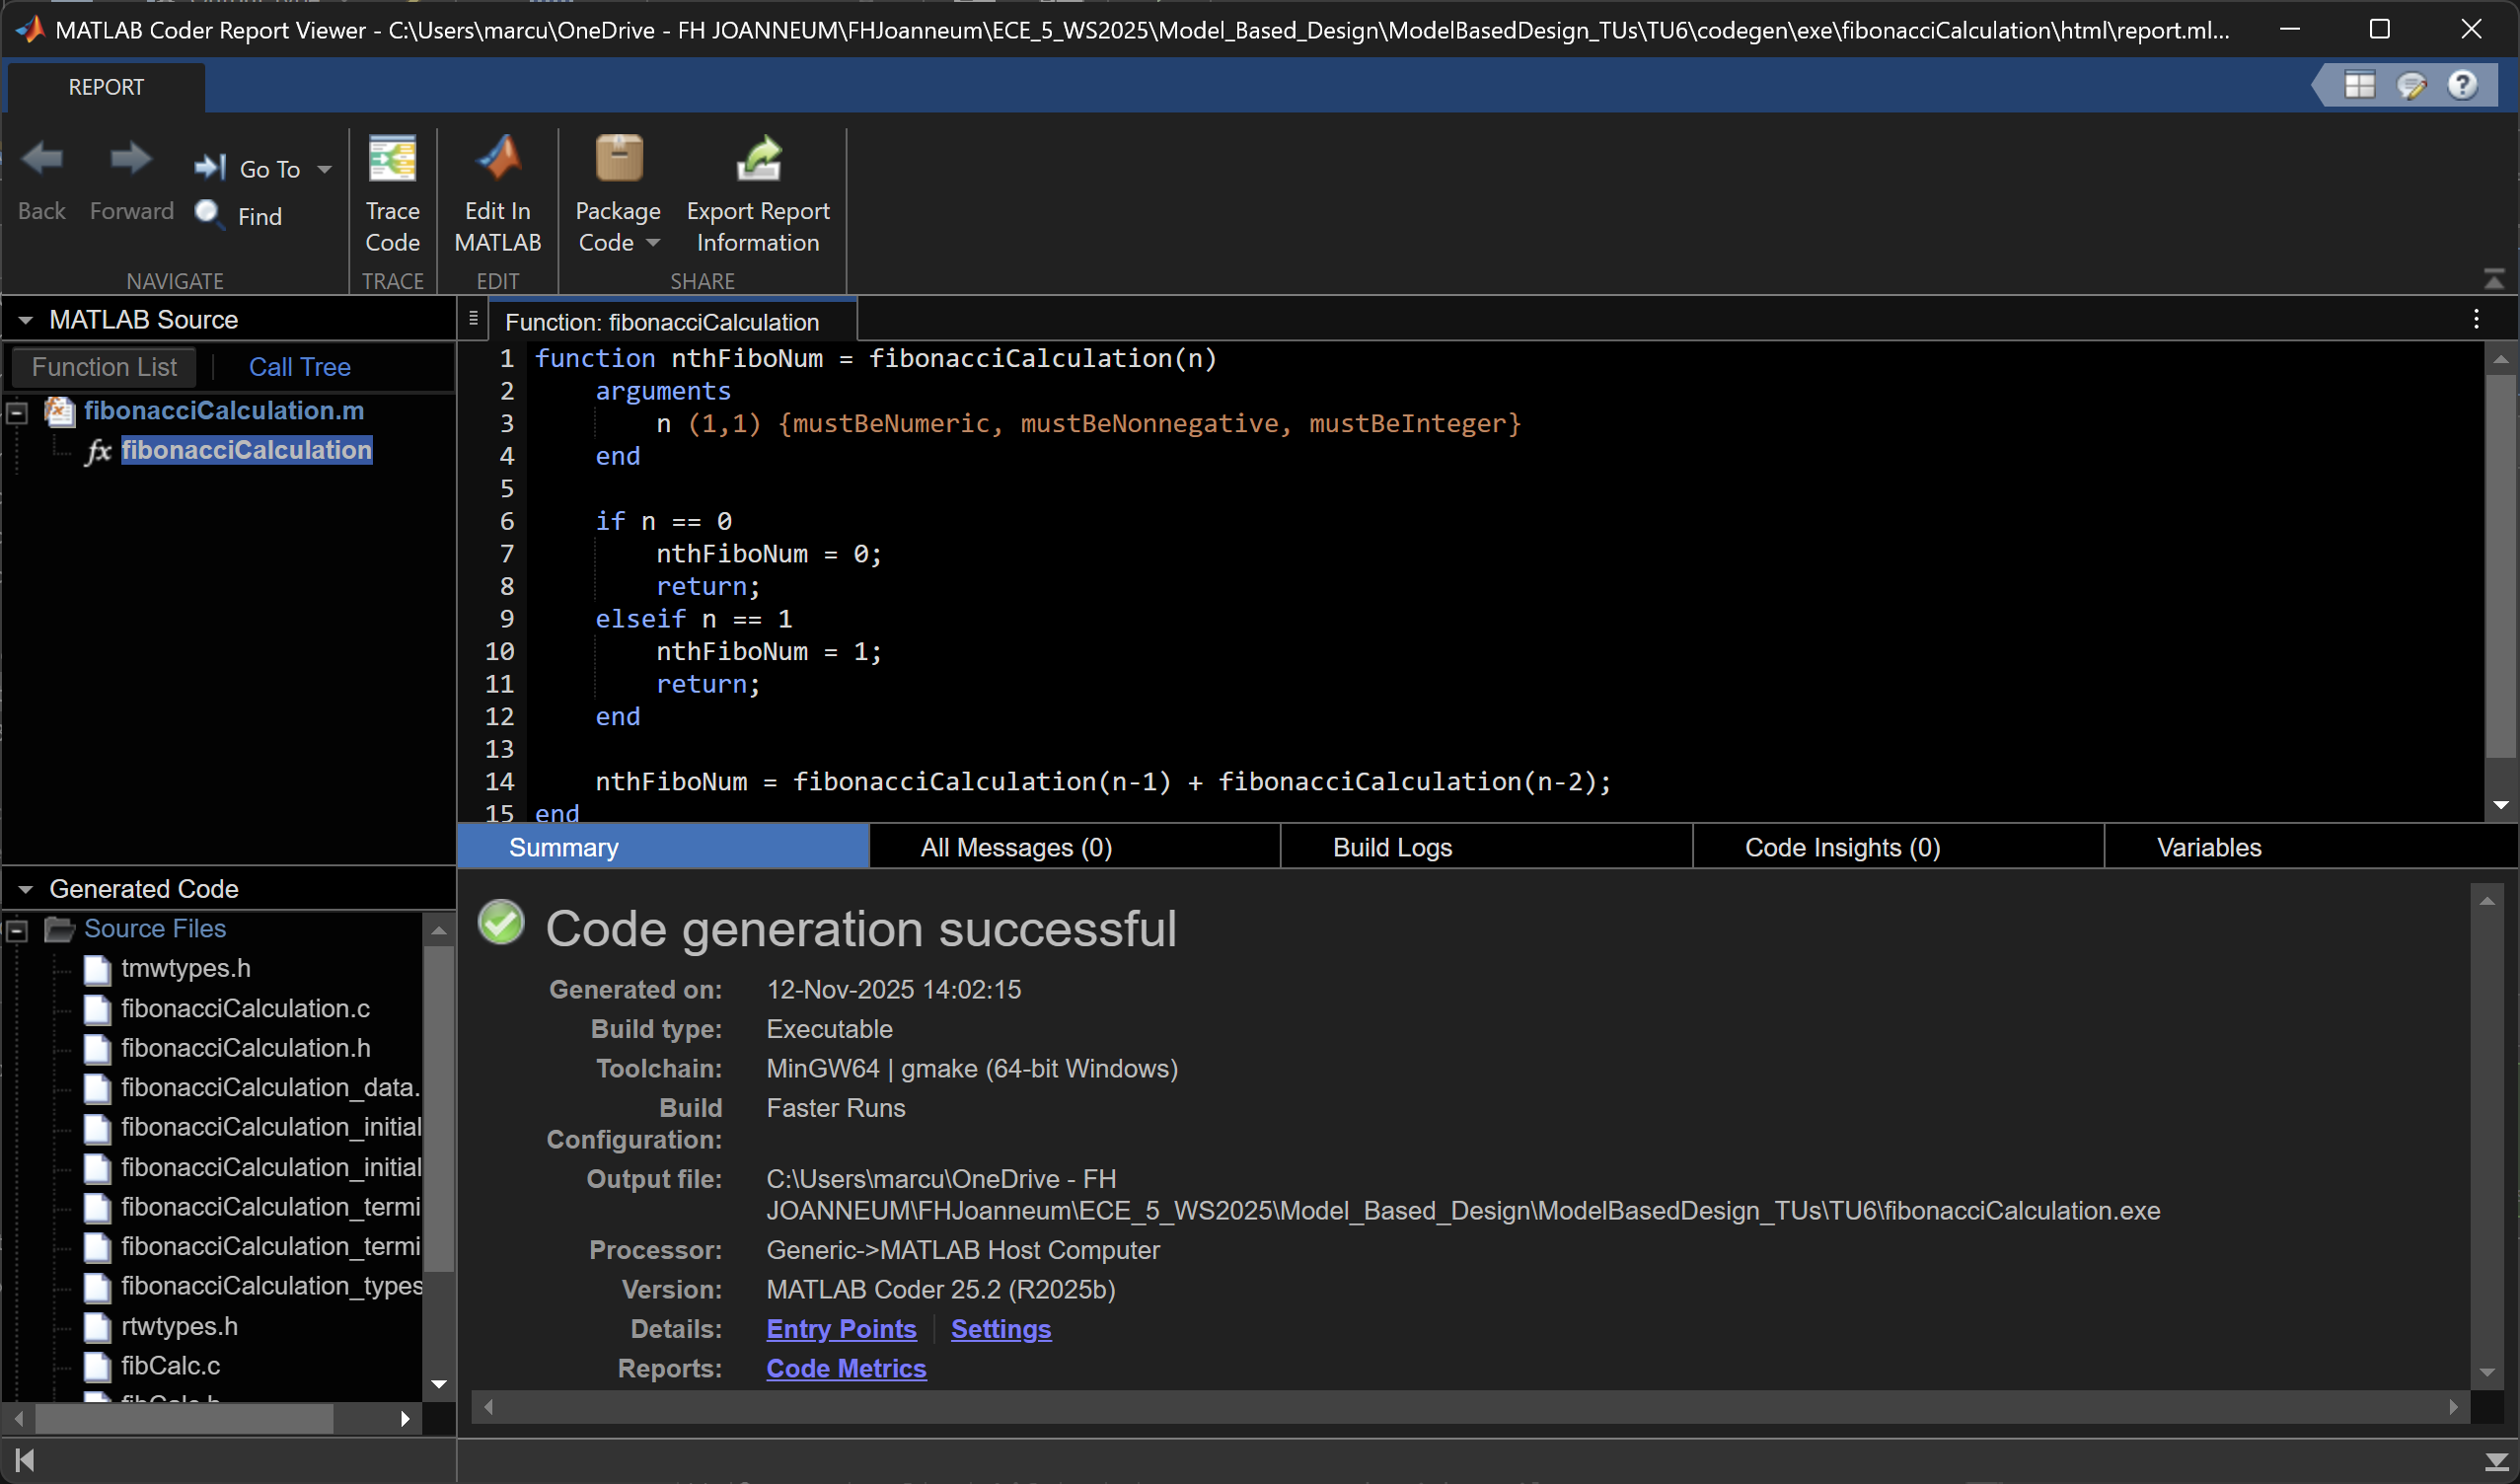

The second screenshot shows the resulting folder structure, listing the numerous C source files, header files, and auxiliary files created by the coder in the codegen/exe directory, which are necessary for compiling the final standalone program.

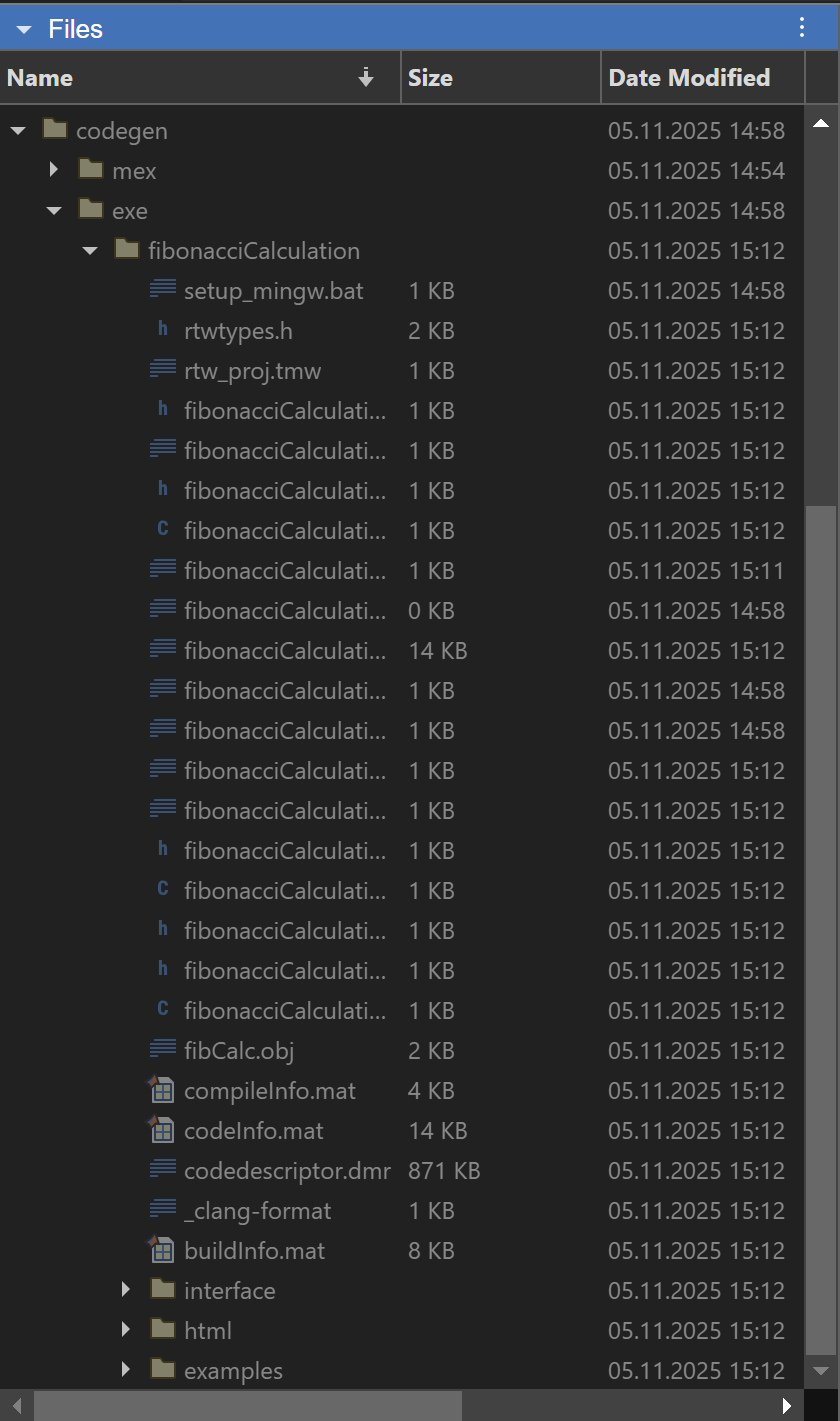

clear

# Training Unit 7: Automatic Code Generation

Fink Lucas / Teichtmeister Marcus, 12.11.2025

## Using the Command Line for MEX Code Generation

First the command *"coder.screener('fibonacciCalculation.m')"* is used. It analyzes the MATLAB file "fibonacciCalculation.m" to determine its suitability for code generation using MATLAB Coder. It generates a report that lists unsupported functions that would prevent the file from being converted into C/C++ code.

Generated Report:

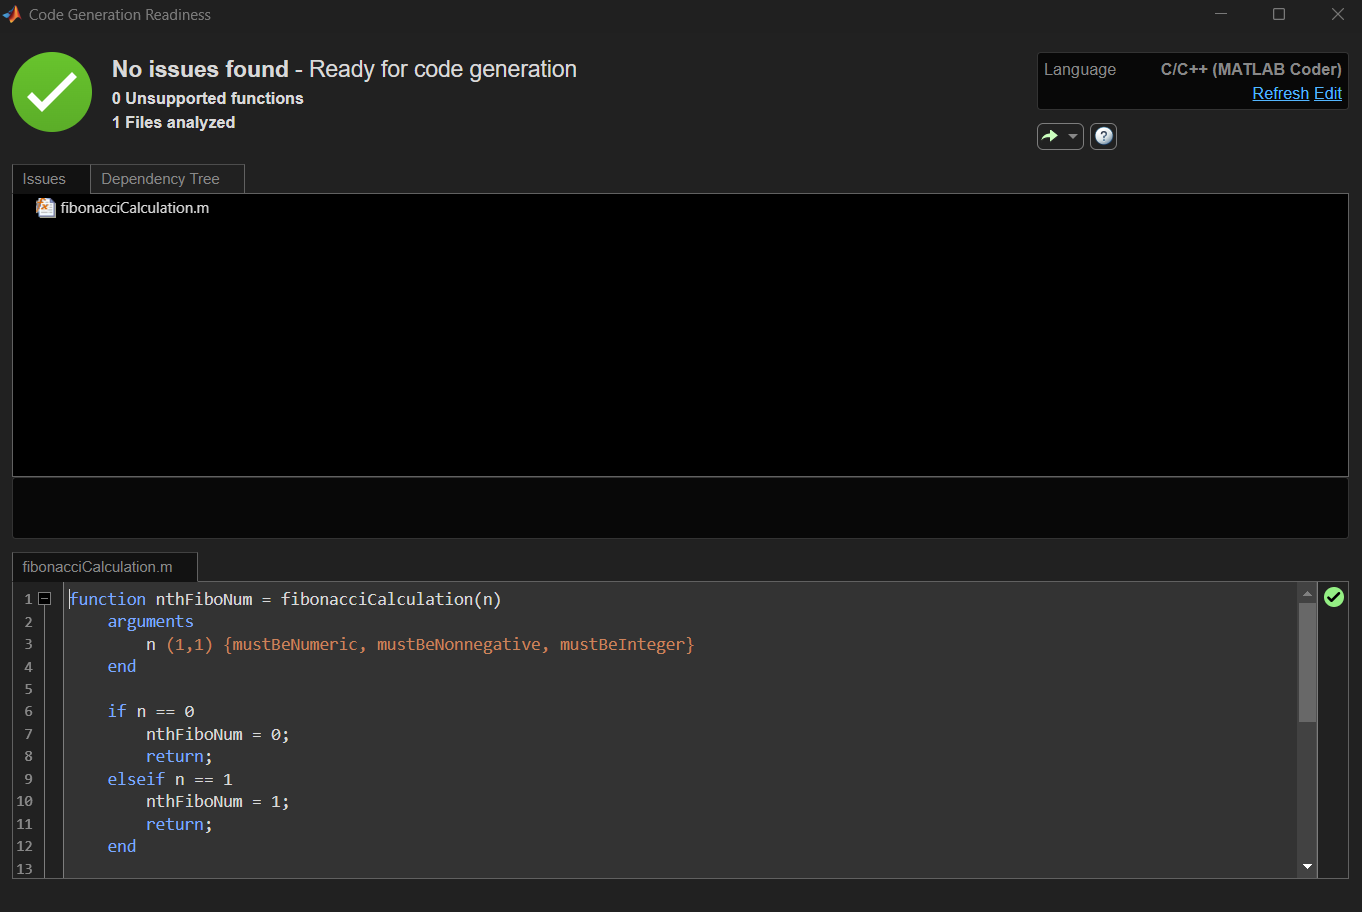

Next the MEX-function is generated using the command *"codegen fibonacciCalculation.m -args {int32(0)}" *uses MATLAB Coder to generate C/C++ source code from the MATLAB function , simultaneously compiling it into a MEX function for accelerated execution within MATLAB, using a scalar 32-bit integer as the specified input type.

Response to the executed command:

## Using the command line for EXE code generation

The code generation process can also be speed-up for binary-files using the command line

First, an exe config file will be generated using the command *"exe_cfg = coder.config('exe')" *which is the same Window which opened for generating an Windows executable with the Matlab Coder App.

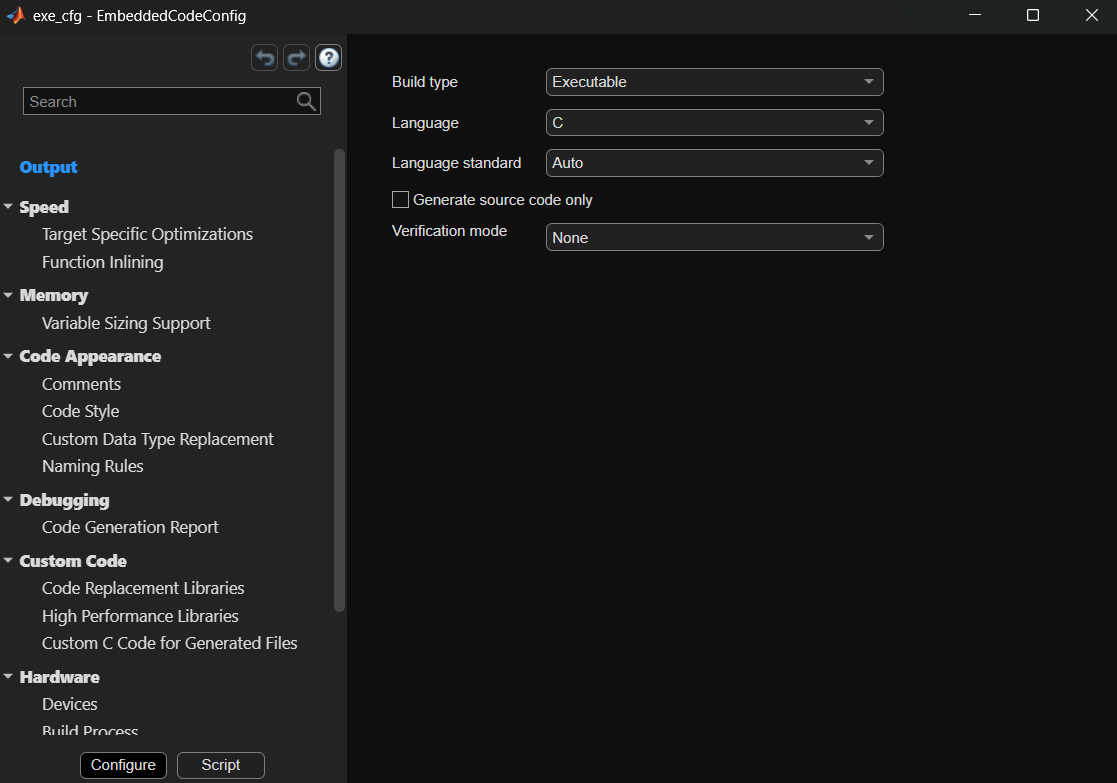

**Code Generation:**

- First try using *"codegen -config exe_cfg fibonacciCalculation.m" *which results in following error message:

*"Warning: Trying to generate EXE target without any custom source may cause compilation failure, either set 'GenerateExampleMain'' to*

*'GenerateCodeAndCompile' or attach a custom source. *

*Unable to determine the class of argument 'n' in entry-point function 'fibonacciCalculation' from the arguments block. Specify the class of*

*this argument in the arguments block using class specification or the 'mustBeA' validator.*

*More information*

*Error in ==> fibonacciCalculation Line: 3 Column: 9*

*Code generation failed: View Error Report"*

- The error message correlates with the message from the code generation:

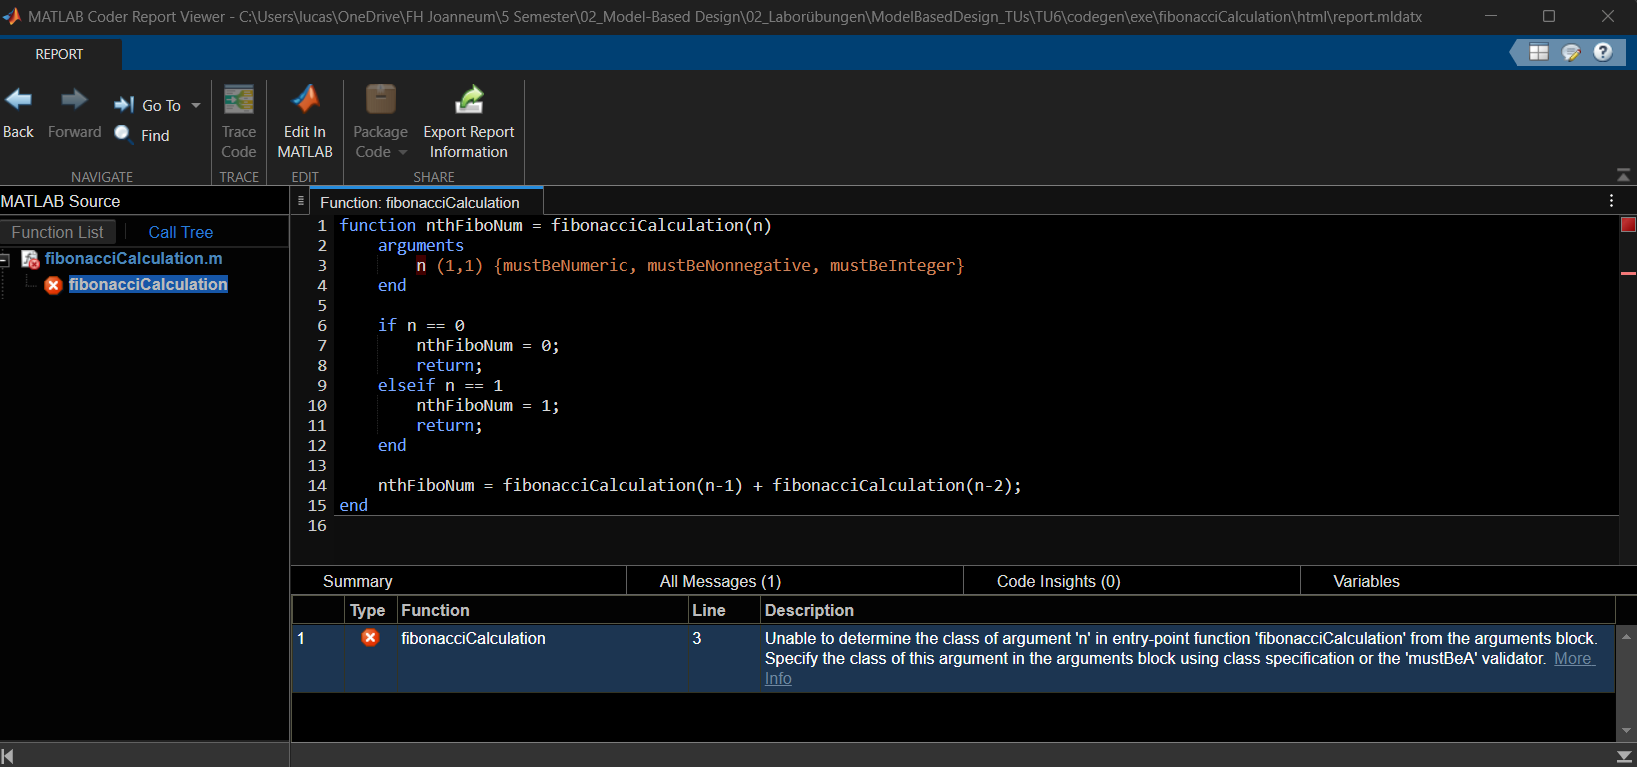

- To successfully generate code a custom main function is required. Since the executable will run outside of MATLAB, it needs a standard C main function (`int main(int argc, char** argv)`) to handle command-line inputs, call the generated function, and manage the output.

- the main function is added to "Additional source files" in the EmbeddedCodeConfig in the section "Custom Code"

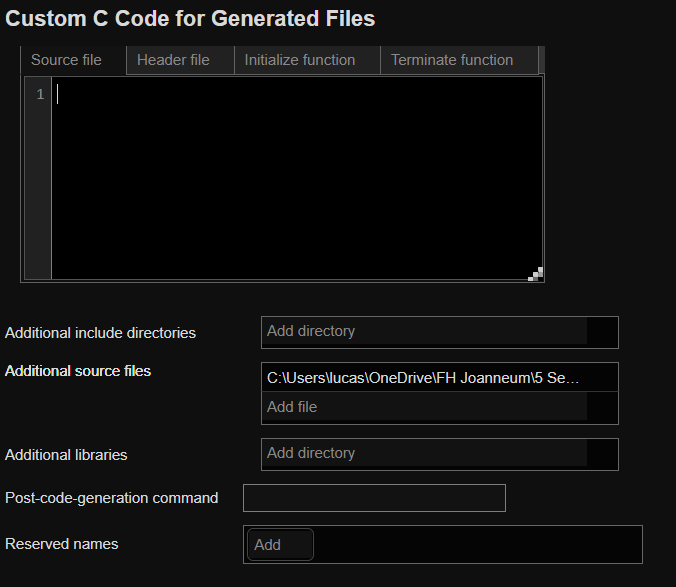

- After that the input arguments need to be specified again. Then the code can be generated using *"codegen -config exe_cfg fibonacciCalculation.m -args {int32(0)}"*

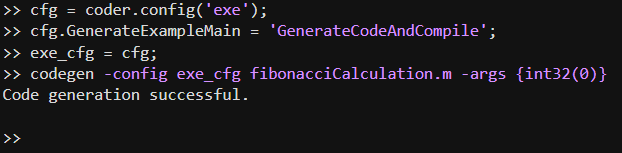

## Calling the binary file (*.exe) in the Matlab environment

Testing to call the binary file within Matlab live script using a the system()-command. Additional, the Fibonacci number to be calculated is passed along during the system call.

result = system('cmd /C fibonacciCalculation.exe 8')

Fibonacci(8) = 21 


result =     21.0000e+000

The return value is correct, therefore the system call can be used for turther performance testing

clear

## Function performance testing with the binary file

The performance of the binary file compared to the MEX and the m-function will now be evaluated

n_test = [8, 20, 30]; 
num_runs = 50; 
exe_file_name = 'fibonacciCalculation.exe';

mean_matlab_times = zeros(1, length(n_test));
mean_mex_times= zeros(1, length(n_test));
mean_exe_times = zeros(1, length(n_test));

for k = 1:length(n_test) 
    n_current = n_test(k);
    
    time_matlab_current = zeros(1, num_runs);
    time_mex_current = zeros(1, num_runs);
    time_exe_current = zeros(1, num_runs);
    
    % 1. MATLAB Function Timing
    for i = 1:num_runs
        tic;
        fibonacciCalculation(n_current); 
        time_matlab_current(i) = toc;
    end
    mean_matlab_times(k) = mean(time_matlab_current);
    
    % 2. MEX Function Timing
    for i = 1:num_runs
        tic;
        fibonacciCalculation_mex_TU6(n_current); 
        time_mex_current(i) = toc;
    end
    mean_mex_times(k) = mean(time_mex_current);

    % 2. EXE Function Timing
    for i = 1:num_runs
        command_str = sprintf('cmd /C %s %d', exe_file_name, n_current);
        tic;
        [status, result_text] = system(command_str);
        time_exe_current(i) = toc;
    end
    mean_exe_times(k) = mean(time_exe_current);
    
end

Displaying the results of the performance analysis

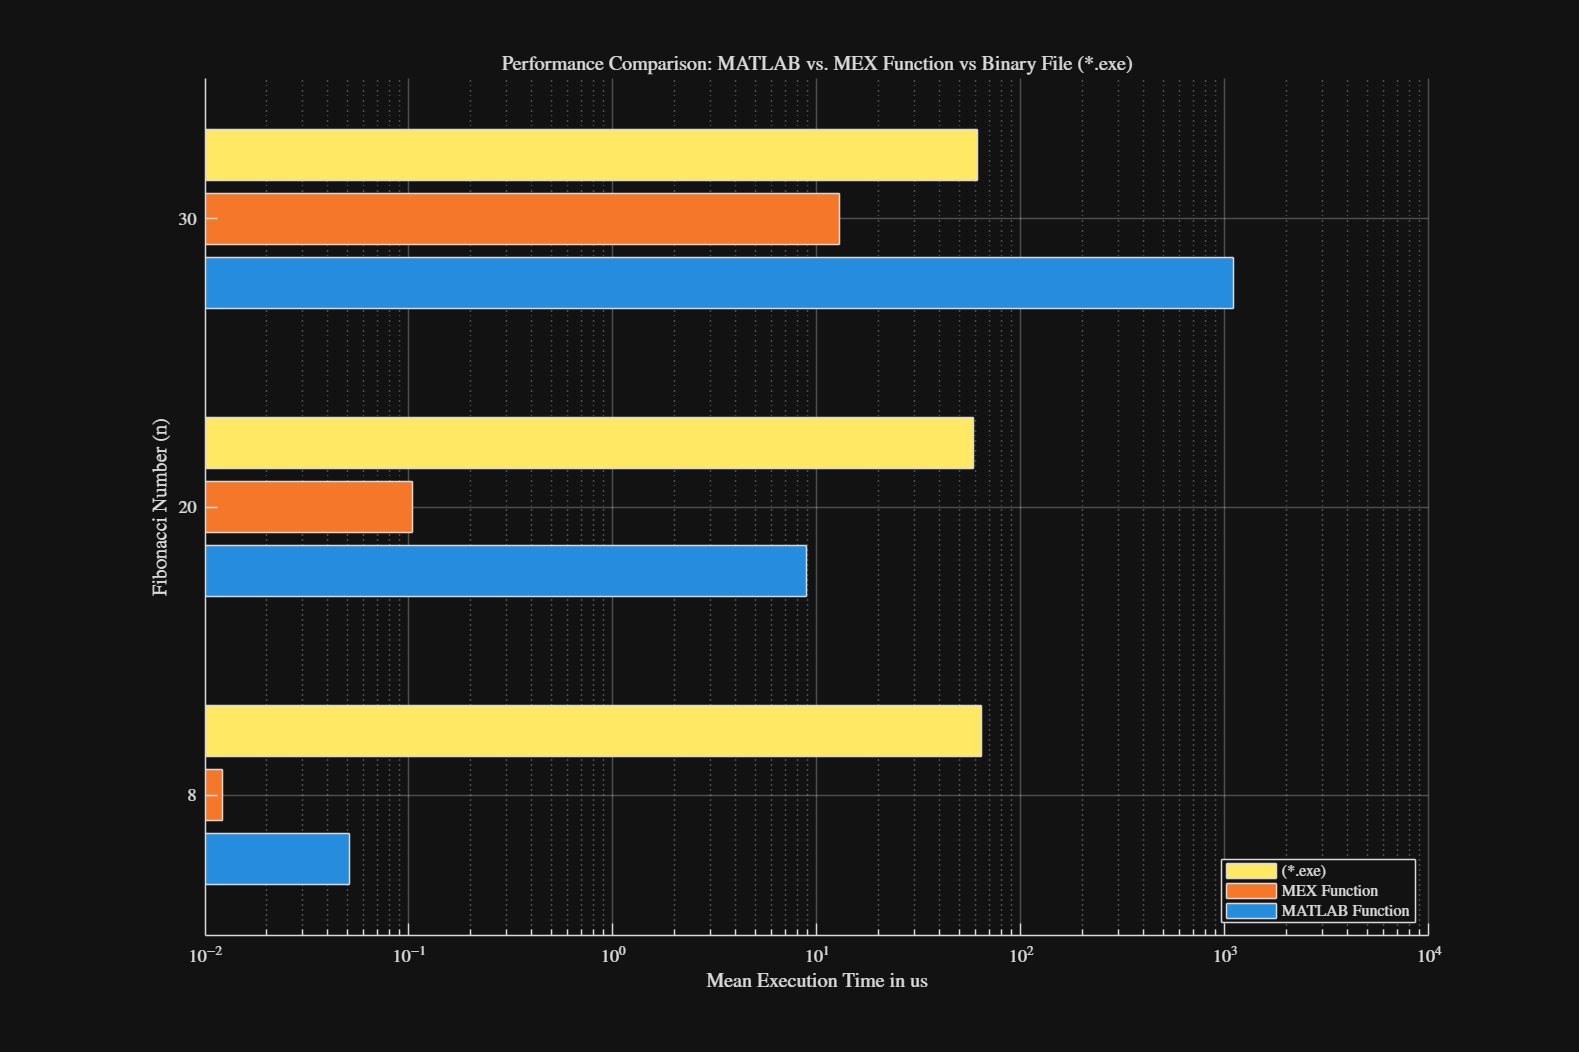

DataMatrix = [mean_matlab_times' * 1000, ...
              mean_mex_times' * 1000, ...
              mean_exe_times' * 1000]; 
clf
figure('Units', 'normalized', 'Position', [0.1 0.1 0.7 0.7]);
h_bar = barh(DataMatrix); 
yticks(1:length(n_test));
yticklabels(cellstr(num2str(n_test'))); 
set(gca, 'Xscale', 'log')
xlabel('Mean Execution Time in us');
ylabel('Fibonacci Number (n)');
title('Performance Comparison: MATLAB vs. MEX Function vs Binary File (*.exe)');
legend({'MATLAB Function', 'MEX Function', '(*.exe)'}, 'Location', 'SouthEast');
grid on;
box off;

- For small n, the time required to call an external binary file using the system() command dominates the total execution time. This operating system overhead makes the binary file (*.exe) the slowest method for small n.

- The MEX Function provides the best performance for moderate computational loads. By executing highly optimized, pre-compiled C/C++ code directly within the MATLAB environment, it minimizes the overhead and has better computational speed.

- Binary File (*.exe) excels with at high laods. For complex, time-consuming calculations, the true computation time of the algorithm eventually outweighs the fixed overhead of the system() call. When this point is reached, the standalone Binary File becomes the fastest method.

clear

##  Simulink implementation of Fibonacci function in a Matlab function

Now, the Fibonacci function is implemented in Simulink. The implementation is done using an MATLAB function block.

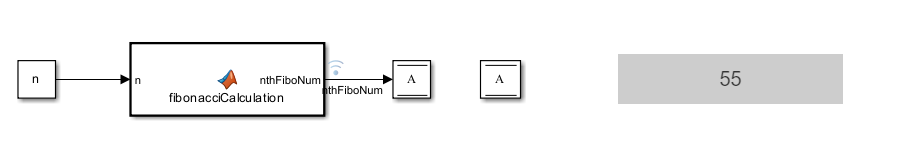

First up the functionality of the model is in the Live script

n = 10;
sim('FiboSimulink.slx')
result = FiboSimulink_nthFiboNum.get('nthFiboNum').Values.Data

result =     55.0000e+000

Additionally, the functionality is tested using the MATLAB Command Window using the command: sim('FiboSimulink.slx')

n = 12;

This command returns the same Dataset with the calculation Value than before in the Live script

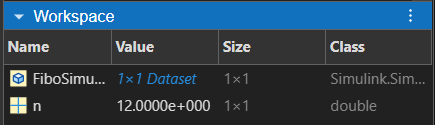

clear

### Testing the Simulink Model using different “Simulation Modes”

Now, the same Simulink model with the fibonacci function is being tested, just using different Simulation Modes. The impact of the Simulation Modes on simulation run times over different sizes of n and stop_times is analyzed and also if the build times have any effect on the outcome. The Simulation Modes which are being compared are:

- Normal

- Accelerator

- Rapid Accelerator

%% Performance-Analysis: Normal vs. Accelerator vs. Rapid Accelerator
n_values = [10, 20, 40];    
stop_times = [0.9, 2.0]; 

num_n = length(n_values);
num_times = length(stop_times);

results_all = cell(num_times, 1);

for j = 1:num_times
    stop_time = stop_times(j);
    
    results_current = zeros(num_n, 4);

    for i = 1:num_n
        n = n_values(i);

        assignin('base', 'n', n);
        
        % --- Modues 1: Normal ---
        tic;
        sim('FiboSimulink.slx', 'SimulationMode', 'normal', 'StopTime', num2str(stop_time));
        time_normal = toc;
        
        % --- Modus 2: Accelerator ---

        tic;
        sim('FiboSimulink_Accelerator.slx', 'SimulationMode', 'accelerator', 'StopTime', num2str(stop_time));
        time_accel_run = toc;

        % --- Modus 3: Rapid Accelerator ---
        tic;
        sim('FiboSimulink_RapidAccelerator.slx', 'SimulationMode', 'rapid-accelerator', 'StopTime', num2str(stop_time));
        time_rapid_run = toc;
        
        results_current(i, :) = [n, time_normal, time_accel_run, time_rapid_run];
    end
    
    col_names = {'n', 'Normal', 'Accelerator_Run', 'Rapid_Accelerator_Run'};
    results_all{j} = array2table(results_current, 'VariableNames', col_names);
end

### Searching for referenced models in model 'FiboSimulink_RapidAccelerator'.
### Total of 1 models to build.
### Searching for referenced models in model 'FiboSimulink_RapidAccelerator'.
### Total of 1 models to build.
### Searching for referenced models in model 'FiboSimulink_RapidAccelerator'.
### Total of 1 models to build.
### Searching for referenced models in model 'FiboSimulink_RapidAccelerator'.
### Total of 1 models to build.
### Searching for referenced models in model 'FiboSimulink_RapidAccelerator'.
### Total of 1 models to build.
### Searching for referenced models in model 'FiboSimulink_RapidAccelerator'.
### Total of 1 models to build.


When looking at the output from the calculation it can be seen that the Rapid Accelerator mode must rebuild its model everytime n changes,  because the code generator treats the value n as a structural dependency that affects the number of loops or computational complexity in the resulting C code. This rebuild ensures the generated binary remains optimally compiled and accurate for the specific computational load defined by the new n.

Next, the performance of the different Simulation Modes is displayed for different n and stop_times.

figure('Name', 'Performance-Matrix: Computational Load vs. Simulation Duration', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.5]);

for k = 1:num_times
    subplot(1, 2, k); 
    
    current_table = results_all{k};
    
    b = bar(current_table.n, current_table{:, {'Normal', 'Accelerator_Run', 'Rapid_Accelerator_Run'}});


    title(sprintf('Performance for Stop Time = %.1f s', stop_times(k)));
    xlabel('Fibonacci Number (n) - Computational Load');
    ylabel('Time in s');
    grid on;
    
    if k == 1
        legend('Normal Mode', 'Accelerator Run', 'Rapid Accelerator Run', 'Location', 'NorthWest');
    end
end

sgtitle('Performance Comparison: Effect of Computational Load (n) and Simulation Duration (stop\_time)');

- For low computational loads (n=10), Rapid Accelerator Mode is by far the slowest. This is because the one-time cost of building the C-code executable (which takes ~10-20 seconds) is significantly larger than the actual calculation time. Normal and Accelerator modes are fastest here, as they have minimal startup overhead.

- As the computational load increases (n=40), this relationship flips. The Normal and Accelerator modes become extremely slow as they must interpret the slow Fibonacci function repeatedly. In contrast, Rapid Accelerator is now the fastest mode, as the initial build-time penalty is paid off by the massive speedup from running a highly-optimized, pre-compiled executable.

- Increasing the stop_time (from 0.9s to 2.0s) worsens the performance of Normal and Accelerator modes, as they must run the slow calculation for a longer duration, especially with higher work loads. The total time for Rapid Accelerator, however, is dominated by the build time, so the simulation duration has a comparatively minor impact on its total time.

## Simulink implementation of Fibonacci function in a Stateflow function

Now, the Fibonacci function is implemented using a Stateflow Chart

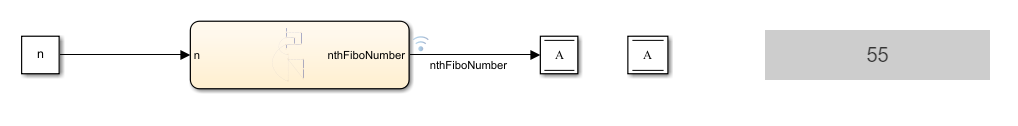

First, the functionality is again tested directly in the Live script

n = 10;
sim('FiboSimulink_StateflowChart.slx');

F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000


result = FiboSimulink_StateflowChart_nthFiboNumber.get('nthFiboNumber').Values.Data

result =     55.0000e+000

Additionally, the functionality is again tested using the Command Window with the command: sim('FiboSimulink_StateflowChart.slx')

n= 12;

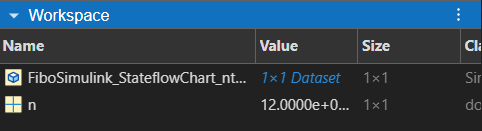

This command returns the same Dataset with the calculation Value than before in the Live script

clearvars -except results_all n_values stop_times

### Testing the Stateflow Model using different “Simulation Modes” and Comparing it to Simulink

Now, the Fibonacci function implemented in the Stateflow chart is being tested, again using different Simulation Modes. The impact of the Simulation Modes on simulation run times over different sizes of n and stop_times is analyzed and also if the build times have any effect on the outcome. The Simulation Modes which are being compared are:

- Normal

- Accelerator

- Rapid Accelerator

%% Performance-Analysis: Normal vs. Accelerator vs. Rapid Accelerator for the Stateflow chart
sf_model_name = 'FiboSimulink_StateflowChart.slx';

sf_results_all = cell(length(stop_times), 1);
num_n = length(n_values);

for j = 1:length(stop_times)
    stop_time = stop_times(j);
    
    sf_results_current = zeros(num_n, 4);

    for i = 1:num_n
        n = n_values(i);
        assignin('base', 'n', n); 

        % --- 1. Normal Mode ---
        tic;
        sim(sf_model_name, 'SimulationMode', 'normal', 'StopTime', num2str(stop_time));
        time_sf_normal = toc;
        
        % --- 2. Accelerator Mode ---
        tic;
        sim(sf_model_name, 'SimulationMode', 'accelerator', 'StopTime', num2str(stop_time));
        time_sf_accelerator = toc;

        % --- 3. Rapid Accelerator Mode ---
        tic;
        sim(sf_model_name, 'SimulationMode', 'rapid-accelerator', 'StopTime', num2str(stop_time));
        time_sf_rapid = toc;
        
        sf_results_current(i, :) = [n, time_sf_normal, time_sf_accelerator, time_sf_rapid];
    end
    
    sf_col_names = {'n', 'SF_Normal', 'SF_Accelerator', 'SF_Rapid'};
    sf_results_all{j} = array2table(sf_results_current, 'VariableNames', sf_col_names);
end

F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000


### Searching for referenced models in model 'FiboSimulink_StateflowChart'.
### Total of 1 models to build.


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003


### Searching for referenced models in model 'FiboSimulink_StateflowChart'.
### Total of 1 models to build.


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003
F2 =
    10.9460e+003
F2 =
    17.7110e+003
F2 =
    28.6570e+003
F2 =
    46.3680e+003
F2 =
    75.0250e+003
F2 =
   121.3930e+003
F2 =
   196.4180e+003
F2 =
   317.8110e+003
F2 =
   514.2290e+003
F2 =
   832.0400e+003
F2 =
     1.3463e+006
F2 =
     2.1783e+006
F2 =
     3.5246e+006
F2 =
     5.7029e+006
F2 =
     9.2275e+006
F2 =
    14.9304e+006
F2 =
    24.1578e+006
F2 =
    39.0882e+006
F2 =
    63.2460e+006
F2 =
   102.3342e+006


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003
F2 =
    10.9460e+003
F2 =
    17.7110e+003
F2 =
    28.6570e+003
F2 =
    46.3680e+003
F2 =
    75.0250e+003
F2 =
   121.3930e+003
F2 =
   196.4180e+003
F2 =
   317.8110e+003
F2 =
   514.2290e+003
F2 =
   832.0400e+003
F2 =
     1.3463e+006
F2 =
     2.1783e+006
F2 =
     3.5246e+006
F2 =
     5.7029e+006
F2 =
     9.2275e+006
F2 =
    14.9304e+006
F2 =
    24.1578e+006
F2 =
    39.0882e+006
F2 =
    63.2460e+006
F2 =
   102.3342e+006


### Searching for referenced models in model 'FiboSimulink_StateflowChart'.
### Total of 1 models to build.


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000


### Searching for referenced models in model 'FiboSimulink_StateflowChart'.
### Total of 1 models to build.


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    3

F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    3

### Searching for referenced models in model 'FiboSimulink_StateflowChart'.
### Total of 1 models to build.


F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003
F2 =
    10.9460e+003
F2 =
    17.7110e+003
F2 =
    28.6570e+003
F2 =
    46.3680e+003
F2 =
    75.0250e+003
F2 =
   121.3930e+003
F2 =
   196.4180e+003
F2 =
   317.8110e+003
F2 =
   514.2290e+003
F2 =
   832.0400e+003
F2 =
     1.3463e+006
F2 =
     2.1783e+006
F2 =
     3.5246e+006
F2 =
     5.7029e+006
F2 =
     9.2275e+006
F2 =
    14.9304e+006
F2 =
    24.1578e+006
F2 =
    39.0882e+006
F2 =
    63.2460e+006
F2 =
   102.3342e+006
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    2

F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    21.0000e+000
F2 =
    34.0000e+000
F2 =
    55.0000e+000
F2 =
    89.0000e+000
F2 =
   144.0000e+000
F2 =
   233.0000e+000
F2 =
   377.0000e+000
F2 =
   610.0000e+000
F2 =
   987.0000e+000
F2 =
     1.5970e+003
F2 =
     2.5840e+003
F2 =
     4.1810e+003
F2 =
     6.7650e+003
F2 =
    10.9460e+003
F2 =
    17.7110e+003
F2 =
    28.6570e+003
F2 =
    46.3680e+003
F2 =
    75.0250e+003
F2 =
   121.3930e+003
F2 =
   196.4180e+003
F2 =
   317.8110e+003
F2 =
   514.2290e+003
F2 =
   832.0400e+003
F2 =
     1.3463e+006
F2 =
     2.1783e+006
F2 =
     3.5246e+006
F2 =
     5.7029e+006
F2 =
     9.2275e+006
F2 =
    14.9304e+006
F2 =
    24.1578e+006
F2 =
    39.0882e+006
F2 =
    63.2460e+006
F2 =
   102.3342e+006
F2 =
     1.0000e+000
F2 =
     2.0000e+000
F2 =
     3.0000e+000
F2 =
     5.0000e+000
F2 =
     8.0000e+000
F2 =
    13.0000e+000
F2 =
    2

### Searching for referenced models in model 'FiboSimulink_StateflowChart'.
### Total of 1 models to build.


Next, the performance of the different Simulation Modes for the Stateflow chart is displayed for different n and stop_times and compared to the Matlab function in Simulink

combined_results = cell(length(stop_times), 1);

figure('Name', 'Simulink vs. Stateflow: All Modes Comparison', 'Units', 'normalized', 'Position', [0.1 0.1 0.9 0.6]);

for k = 1:length(stop_times)
    sl_table = results_all{k}; 
    sf_table = sf_results_all{k};
    
    combined_data = table( ...
        sl_table.n, ...
        sl_table.Normal, sl_table.Accelerator_Run, sl_table.Rapid_Accelerator_Run, ...
        sf_table.SF_Normal, sf_table.SF_Accelerator, sf_table.SF_Rapid, ...
        'VariableNames', {'n', 'SL_Normal', 'SL_Accel', 'SL_Rapid', 'SF_Normal', 'SF_Accel', 'SF_Rapid'} ...
    );
    combined_results{k} = combined_data;

    % --- Plotting the Comparison ---
    subplot(1, 2, k); 
   
    bar_data = combined_data{:, {'SL_Normal', 'SL_Accel', 'SL_Rapid', 'SF_Normal', 'SF_Accel', 'SF_Rapid'}};
    bar(combined_data.n, bar_data);

    title(sprintf('Performance Comparison for Stop Time = %.1f s', stop_times(k)));
    xlabel('Fibonacci Number (n) - Computational Load');
    ylabel('Time in s');
    
    if k == 1
        legend_labels = {
            'SL: Normal Mode', 'SL: Accelerator Run', 'SL: Rapid Accelerator', ...
            'SF: Normal Mode', 'SF: Accelerator Run', 'SF: Rapid Accelerator'
        };
        legend(legend_labels, 'Location', 'NorthWest', 'NumColumns', 2);
    end
    grid on;
end

sgtitle('Performance Comparison: MATLAB Fcn Block (SL) vs. Stateflow Chart (SF)');

The analysis reveals that the **Stateflow Chart implementation is significantly more performant** than the MATLAB Function Block implementation.

- For high computational load n=40, the Stateflow Rapid Accelerator is the fastest mode overall. At a stop_time of 2s the Stateflow chart takes only ~3s while the SL MATLAB Function block takes significantly longer. This highlights Stateflow's ability to generate exceptionally fast C code with a lower runtime overhead than the Matlab Function.

- The time taken by the Stateflow Rapid Accelerator is nearly identical for n=20 and n=40. This demonstrates that the initial build/compilation time for the optimized executable masks the actual calculation time, displaying that the core Stateflow logic executes extremely quickly, even at high loads.